## Data Selection

trailingXMonths = 18; % Trailing X Months (TXM) analysis will be computed below, for specified X months (which are valid/available)

Identify range of days included within Trailing X Months window:

endDate = datetime("now") - calmonths(1); %first day of prior month (current month never has full data)
startDate = endDate - calmonths(trailingXMonths-1); 

dateRange = datetime(startDate:endDate); % nit: unclear why datetime cast needed

Create equal-length month/year arrays identifying trailing X months here: 

monthStartDates = dateRange(day(dateRange)==1);
monthsTXM = month(monthStartDates);
yearsTXM = year(monthStartDates);
numMonthsStudy = numel(monthsTXM); assert(numMonthsStudy==trailingXMonths); % TODO: deprecated this now-redundant variable

## Data Access & Cleaning

#### Read workbooks

setenv('AWS_DEFAULT_REGION','us-east-2');
s3URI = "s3://vijayiyer05-me-health-metrics";

currT12MFilename = string(datetime("now","Format","yyyyMM")) + "StepsMonthlyT12M.csv"

currT12MFilename = "202409StepsMonthlyT12M.csv"

TCurr = readtable(s3URI + "/" + currT12MFilename,'TextType',"string",'ReadRowNames',true);

if trailingXMonths > 11
    priorT12MFilename = string(datetime("now","Format","yyyyMM")-calmonths(12)) + "StepsMonthlyT12M.csv"
    TPrior = readtable(s3URI + "/" + priorT12MFilename,'TextType',"string",'ReadRowNames',true);
    multiFile = true;
else
    multiFile = false;
end

priorT12MFilename = "202309StepsMonthlyT12M.csv"

#### Append Tables

if multiFile
    T = [TPrior;TCurr];  
else
    T = TCurr;
end

#### Clean Variable Names

% Steps variable (column 2)
Tclean = renamevars(T,"Actual","Steps");

#### Create Trailing X Month table 

% Match months by matching day-removed string representations
monthsTXMStr = string(datetime(yearsTXM,monthsTXM,1,"Format","MMM yyyy")); 
TTrailingX = Tclean(contains(string(Tclean.Row),monthsTXMStr),:)

TTrailingX = 18x1 table
                  Steps   
                __________

    Mar 2023    1.0589e+05
    Apr 2023    1.1648e+05
    May 2023    1.2386e+05
    Jun 2023    1.3692e+05
    Jul 2023    1.4252e+05
    Aug 2023      1.48e+05
    Sep 2023    1.9303e+05
    Oct 2023     2.068e+05
    Nov 2023     1.474e+05
    Dec 2023    1.3943e+05
    Jan 2024    1.7797e+05
    Feb 2024    1.3428e+05
    Mar 2024    1.4581e+05
    Apr 2024    1.2591e+05
    May 2024     1.645e+05
    Jun 2024    1.6118e+05


## Trailing X Months Visualization

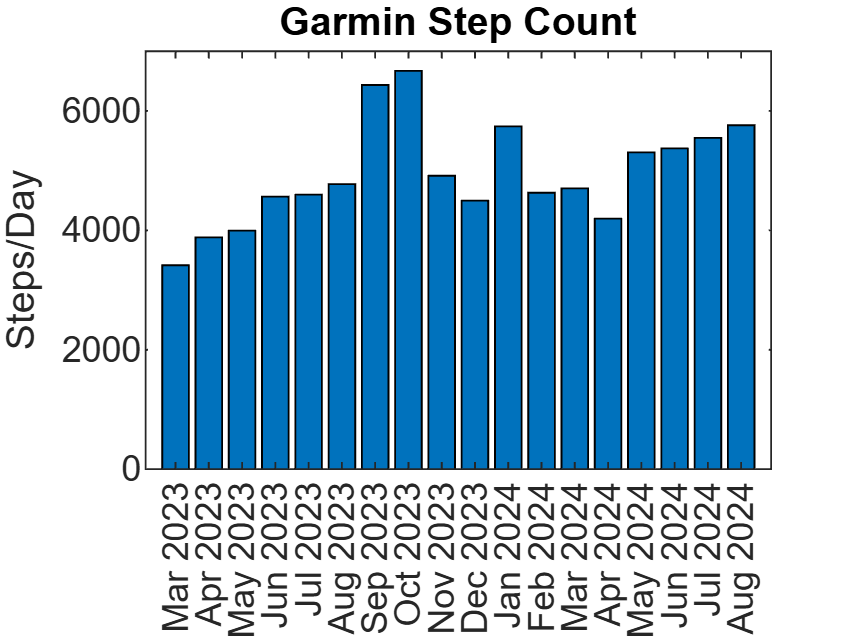

%monthsTXMCat = categorical(monthsTXMStr);
%monthsTXMCat = reordercats(monthsTXMCat,TTrailingX.Row);

daysPerMonth = eomday(yearsTXM,monthsTXM)';

%TODO: Handle skip days by cross-referencing incapacity episodes file

bar(TTrailingX.Row,TTrailingX.Steps./daysPerMonth);
ylabel("Steps/Day")
title("Garmin Step Count")